Author: **Arjan Gupta**

Due: March 27, 2023

Class: RBE 501

Institution: Worcester Polytechnic Institute

# Forward Dyanamics of Three Link Manipuator

clear; clc; close all;

## Build Robot

### Create Rigid Body Elements

First, let us create a `rigidBodyTree` robot model. Then, we create the 3 rectangular arms of the robot. We also create a fourth body for the gripper of the robot which will eventually hold a wrench.

robot = rigidBodyTree("DataFormat","column");
base = robot.Base;
arm1 = rigidBody("arm1");
arm2 = rigidBody("arm2");
arm3 = rigidBody("arm3");
gripper = rigidBody("gripper");

Next, we create collision objects using the given link lengths in the prompt of this assignment. We use `Pose` in order to shift the frame origin down along the x-axis. The default origin is in the center of the object. 

% Link lengths
L1 = 4.0;
L2 = 3.0;
L3 = 2.0;
% Create collision objects for each body
coll1 = collisionBox(L1,0.2,0.2); % box: length, width, height (x,y,z)
coll1.Pose = trvec2tform([L1/2 0 0]);
coll2 = collisionBox(L2,0.2,0.2);
coll2.Pose = trvec2tform([L2/2 0 0]);
coll3 = collisionBox(L3,0.2,0.2);
coll3.Pose = trvec2tform([L3/2 0 0]);
coll4 = collisionBox(0.2,0.2,0.2);
coll4.Pose = trvec2tform([0.1 0 0]);
% Add the collision bodies to the rigid body objects.
addCollision(arm1,coll1);
addCollision(arm2,coll2);
addCollision(arm3,coll3);
addCollision(gripper,coll4);

### Attach Joints

We specify the joints as revolute and set them to rotate around the z-axis.

jnt1 = rigidBodyJoint("jnt1","revolute");
jnt2 = rigidBodyJoint("jnt2","revolute");
jnt3 = rigidBodyJoint("jnt3","revolute");
jnt4 = rigidBodyJoint("jnt4","revolute");
jnt1.JointAxis = [0 0 1];
jnt2.JointAxis = [0 0 1];
jnt3.JointAxis = [0 0 1];
jnt4.JointAxis = [0 0 1];

In the prompt of this assignment, we are given the following DH table.


$$\matrix{
\text{Link}    	& a_i 	& \alpha_i &  d_i & \theta_i  \cr
1			& 0 			& 0	& 0	& \theta_1			\cr
2			& L_1 		& 0		& 0	& \theta_2		\cr
3			& L_2 			& 0			& 0 & \theta_3	\cr
4 & L_3 & 0 & 0 & \theta_4 \cr
}$$


% Joint variables
theta1 = 0;
theta2 = 0;
theta3 = 0;
% DH table
dhparams = [0 0  0 theta1;
            L1 0 0 theta2;
            L2 0 0 theta3;
            L3 0 0 0];
setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');

### Set Physical Properties

% Masses (in kgs), given in assignment prompt
m1 = 20;
m2 = 15;
m3 = 10;
% Moments of inertia (in kgm^2), given in assignment prompt
I1 = 0.5;
I2 = 0.2;
I3 = 0.1;
% Set the masses
arm1.Mass = m1;
arm2.Mass = m2;
arm3.Mass = m3;
gripper.Mass = 0;
% Set the centers of masses
arm1.CenterOfMass = [L1/2, 0, 0];
arm2.CenterOfMass = [L2/2, 0, 0];
arm3.CenterOfMass = [L3/2, 0, 0];
% Set the inertias
arm1.Inertia = [I1,I1,I1,0,0,0];
arm2.Inertia = [I2,I2,I2,0,0,0];
arm3.Inertia = [I3,I3,I3,0,0,0];

### Assemble Robot

To assemble the robot, we add each joint to the body, and then add the body to the tree.

bodies = {base,arm1,arm2,arm3,gripper};
joints = {[],jnt1,jnt2,jnt3,jnt4};
for i = 2:length(bodies)
    bodies{i}.Joint = joints{i};
    addBody(robot,bodies{i},bodies{i-1}.Name)
end

## Problem 1

In this problem we implement the forward dynamics and plot the joint accelerations and velocities in response to actuator torques.

% Set gravity direction
robot.Gravity = [0; -9.81; 0];
% Set joint torques and velocities, as given in assignment prompt
jointTorqs = [20;5;1;0];
jointVelsInit = [0;0;0;0];
% Set initial position, as given in assignment prompt
initialPosition = [-pi/3;pi/2;pi/6;0];

We want to calculate the forward dynamics over a time period. Let us choose a time period of 10 seconds with 10 ms step.

First, we define a time array and time increment (step) size.

time_step = 0.08; % arbitrarily small time step
time_arr = 0:time_step:5;
[~,time_arr_len] = size(time_arr);

Now we can run a loop of calculations for the forward dynamics over this time.

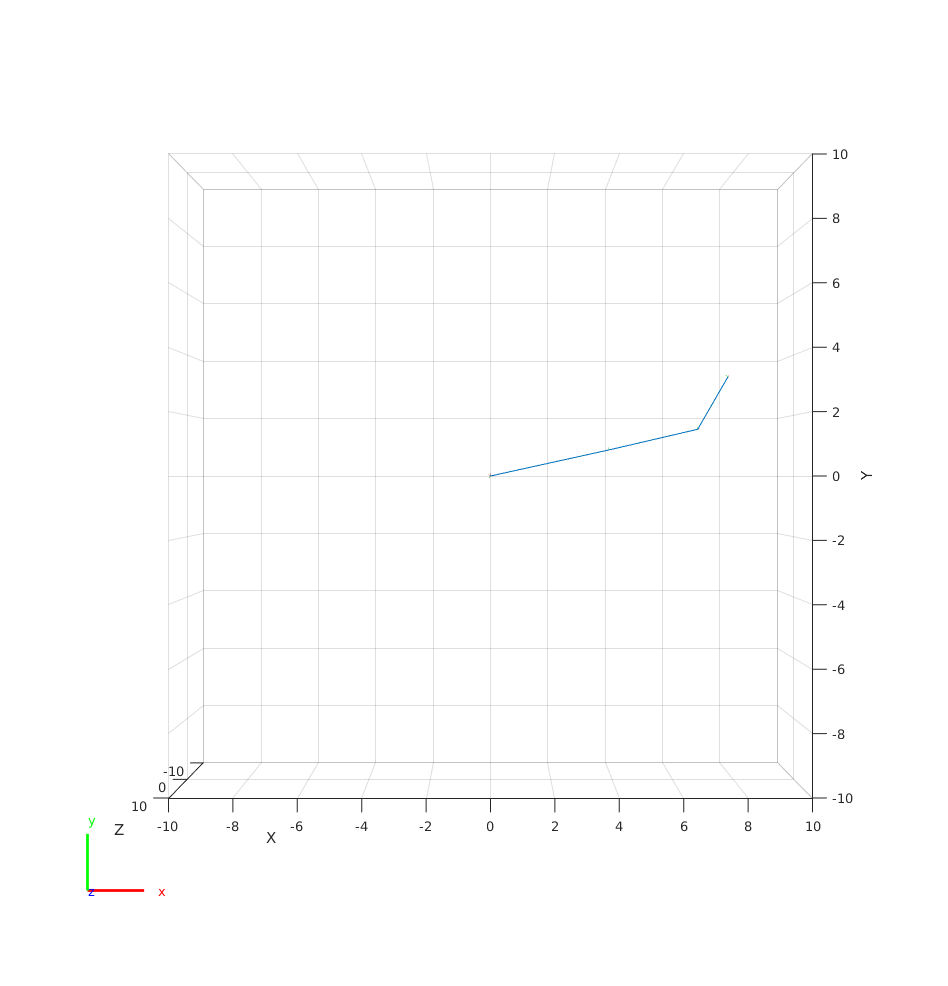

% Declare 3D arrays to capture lists of acceleration, velocity, and
% position vectors
jointAccels = zeros(4,1,time_arr_len);
jointVels = zeros(4,1,time_arr_len+1);
jointVels(:,:,1) = jointVelsInit;
jointAngles = zeros(4,1,time_arr_len+1);
jointAngles(:,:,1) = initialPosition;
i = 1;
% Run the loop for forward dynamics
for t = time_arr
    jointAccels(:,:,i) = forwardDynamics(robot,jointAngles(:,:,i),jointVels(:,:,i),jointTorqs);
    jointVels(:,:,i+1) = jointVels(:,:,i) + jointAccels(:,:,i)*time_step;
    jointAngles(:,:,i+1) = jointAngles(:,:,i) + jointAccels(:,:,i)*time_step*time_step;
    i = i + 1;
    % View the robot as it moves
    if (mod(t,0.1)==0)
        show(robot,jointAngles(:,:,i));
        view(2);
        drawnow;
    end
end

In order to plot the data, we flatten the arrays for acceleration and velocities into their own 2D arrays.

% Acceleration 2D arrays
accel_joint1 = reshape(jointAccels(1,1,:),[1,time_arr_len]);
accel_joint2 = reshape(jointAccels(2,1,:),[1,time_arr_len]);
accel_joint3 = reshape(jointAccels(3,1,:),[1,time_arr_len]);

% Velocity 2D arrays
vel_joint1 = reshape(jointVels(1,1,:),[1,time_arr_len+1]);
vel_joint2 = reshape(jointVels(2,1,:),[1,time_arr_len+1]);
vel_joint3 = reshape(jointVels(3,1,:),[1,time_arr_len+1]);

Now we come up with the acceleration and velocity evolution plots.

### Plot acceleration values against time

Let us now view our joint accelerations against time.

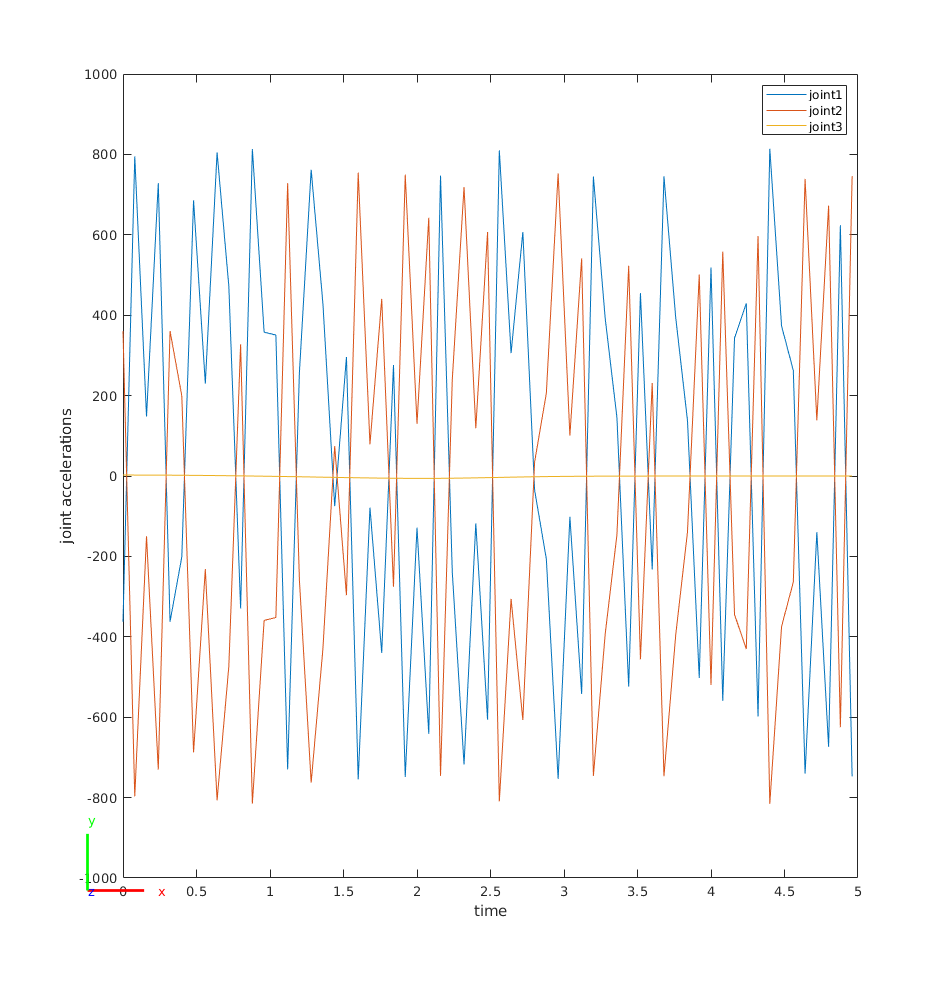

plot(time_arr, accel_joint1)
hold on
plot(time_arr, accel_joint2)
hold on
plot(time_arr, accel_joint3)
xlabel("time")
ylabel("joint accelerations")
xlim([0,5])
ylim([-1000,1000])
legend('joint1','joint2','joint3')
hold off

### Plot velocity values against time

Let us also plot the joint velcoities versus time.

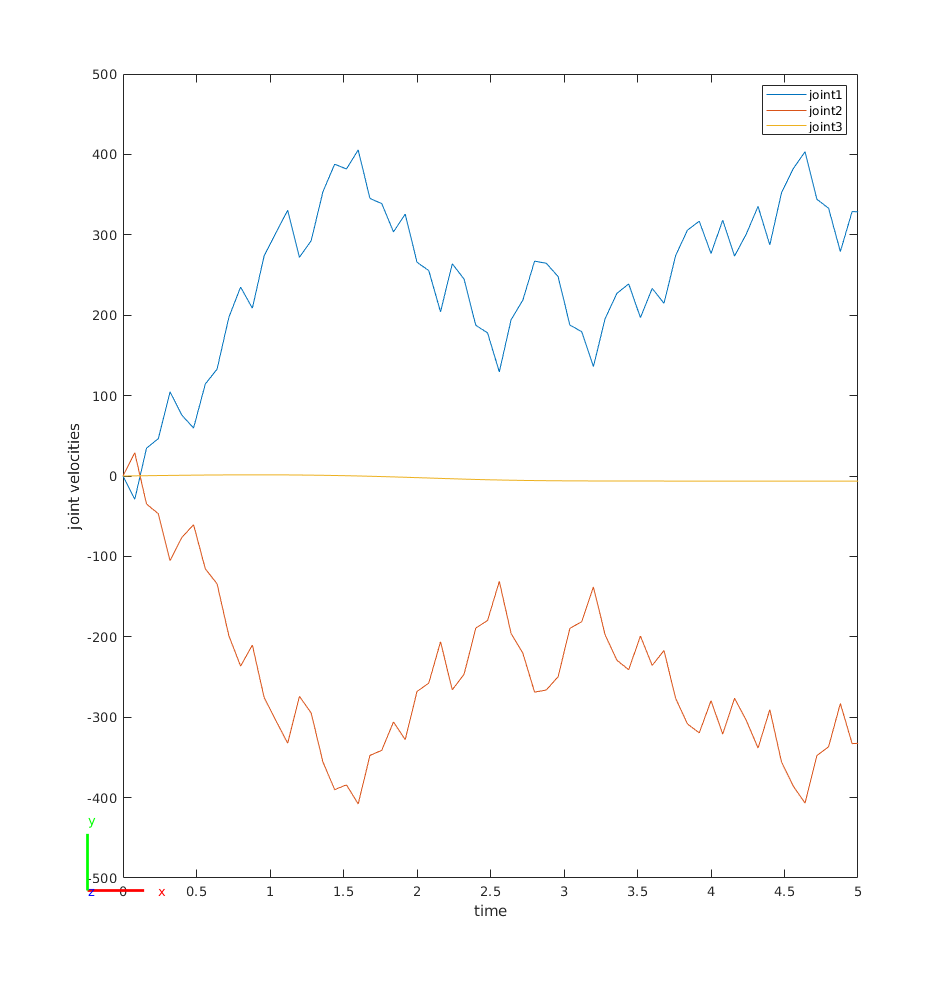

plot([time_arr 10.1], vel_joint1)
hold on
plot([time_arr 10.1], vel_joint2)
hold on
plot([time_arr 10.1], vel_joint3)
xlabel("time")
ylabel("joint velocities")
xlim([0,5])
ylim([-500,500])
legend('joint1','joint2','joint3')
hold off

## Problem 2

For problem 2, we add a wrench to our gripper.

wrench = [0 0 0.5 0 0 0.3];
force_ext = externalForce(robot,'gripper',wrench,initialPosition);

Now we can run a loop of calculations for the forward dynamics over this time.

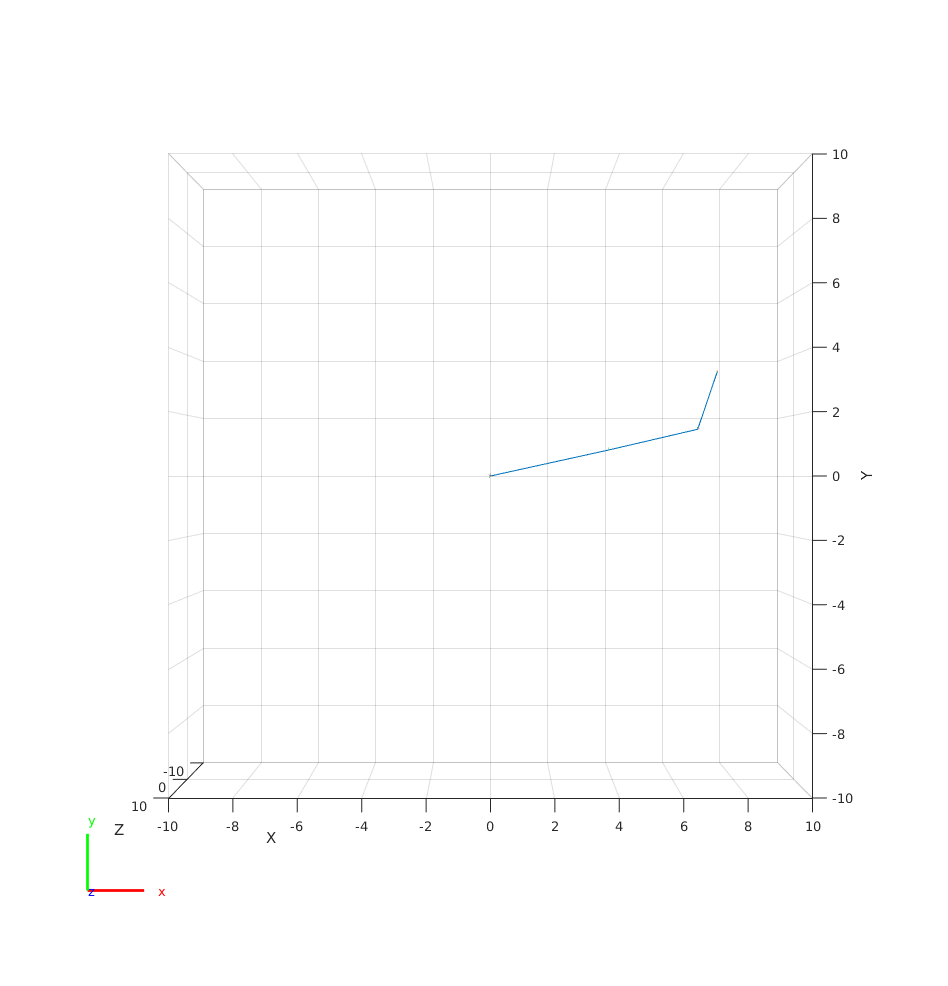

% Declare 3D arrays to capture lists of acceleration, velocity, and
% position vectors
jointAccels = zeros(4,1,time_arr_len);
jointVels = zeros(4,1,time_arr_len+1);
jointVels(:,:,1) = jointVelsInit;
jointAngles = zeros(4,1,time_arr_len+1);
jointAngles(:,:,1) = initialPosition;
i = 1;
% Run the loop for forward dynamics
for t = time_arr
    jointAccels(:,:,i) = forwardDynamics(robot,jointAngles(:,:,i),jointVels(:,:,i),jointTorqs,force_ext);
    jointVels(:,:,i+1) = jointVels(:,:,i) + jointAccels(:,:,i)*time_step;
    jointAngles(:,:,i+1) = jointAngles(:,:,i) + jointAccels(:,:,i)*time_step*time_step;
    i = i + 1;
    % View the robot as it moves
    if (mod(t,0.1)==0)
        show(robot,jointAngles(:,:,i));
        view(2);
        drawnow;
    end
end

In order to plot the data, we flatten the arrays for acceleration and velocities into their own 2D arrays.

% Acceleration 2D arrays
accel_joint1 = reshape(jointAccels(1,1,:),[1,time_arr_len]);
accel_joint2 = reshape(jointAccels(2,1,:),[1,time_arr_len]);
accel_joint3 = reshape(jointAccels(3,1,:),[1,time_arr_len]);

% Velocity 2D arrays
vel_joint1 = reshape(jointVels(1,1,:),[1,time_arr_len+1]);
vel_joint2 = reshape(jointVels(2,1,:),[1,time_arr_len+1]);
vel_joint3 = reshape(jointVels(3,1,:),[1,time_arr_len+1]);

### Plot acceleration values against time

Let us now view our joint accelerations against time.

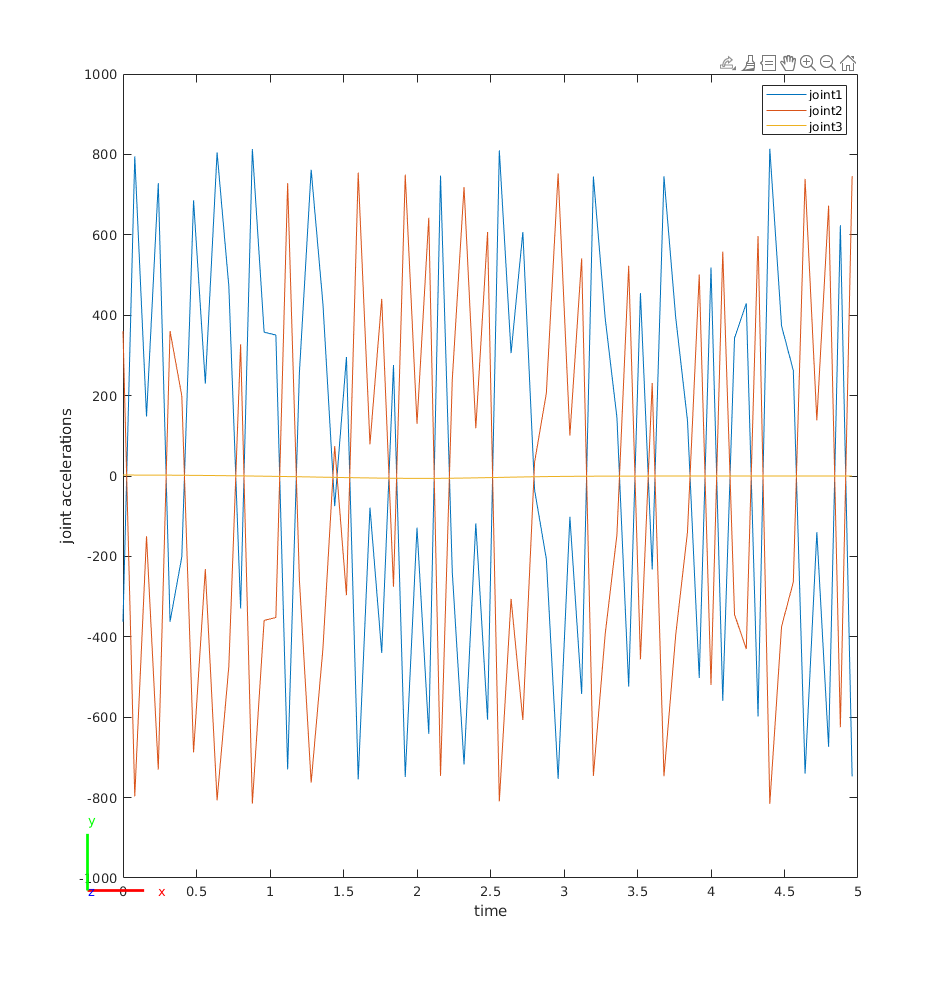

plot(time_arr, accel_joint1)
hold on
plot(time_arr, accel_joint2)
hold on
plot(time_arr, accel_joint3)
xlabel("time")
ylabel("joint accelerations")
xlim([0,5])
ylim([-1000,1000])
legend('joint1','joint2','joint3')
hold off

### Plot velocity values against time

Let us also plot the joint velcoities versus time.

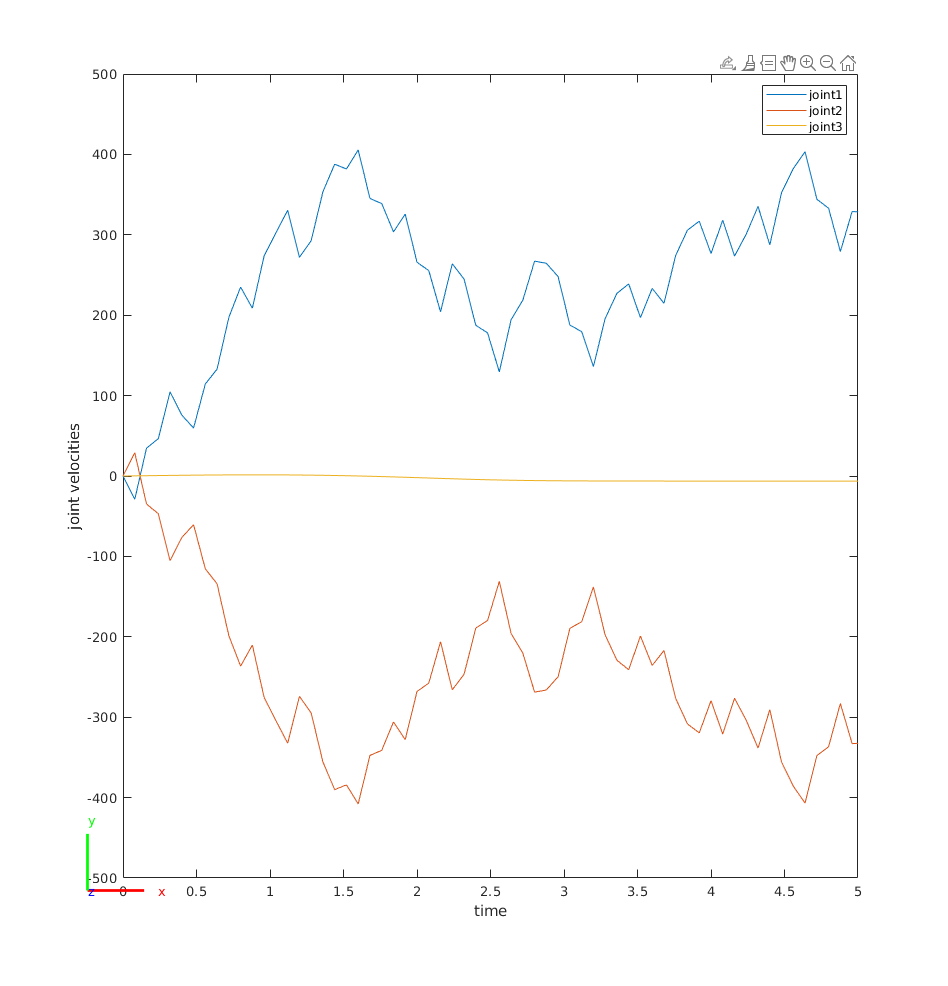

plot([time_arr 10.1], vel_joint1)
hold on
plot([time_arr 10.1], vel_joint2)
hold on
plot([time_arr 10.1], vel_joint3)
xlabel("time")
ylabel("joint velocities")
xlim([0,5])
ylim([-500,500])
legend('joint1','joint2','joint3')
hold off